I1 = imread('cameraman.tif');
I2 = imread('Images/I2.jpg');

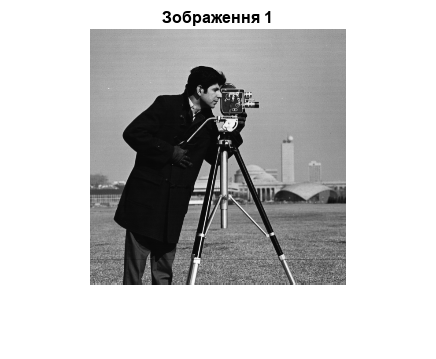

imshow(I1);  
title('Зображення 1');

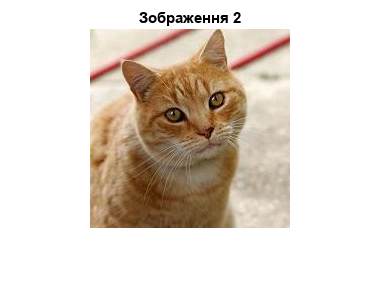

imshow(I2); 
title('Зображення 2');

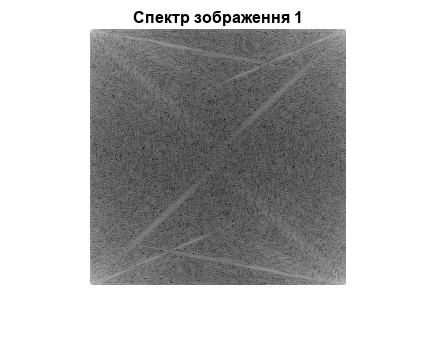

F1 = fft2(I1); 
S1=abs(F1); 
Slog1=log(1+S1); 
imshow(Slog1, [ ]);
title('Спектр зображення 1');

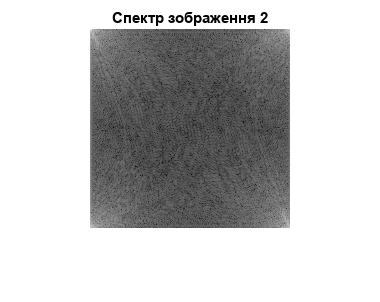

I2 = rgb2gray(I2); 
F2 = fft2(I2); 
S2=abs(F2); 
Slog2=log(1+S2); 
imshow(Slog2, [ ]);
title('Спектр зображення 2');

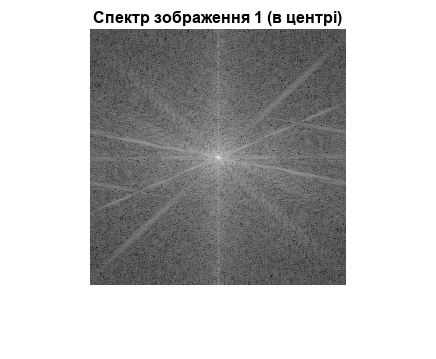

F3 = fft2(I1); 
S3=abs(F3);
Fc3= fftshift(S3); 
Slog3=log(1+Fc3); 
imshow(Slog3, [ ]);
title('Спектр зображення 1 (в центрі)');

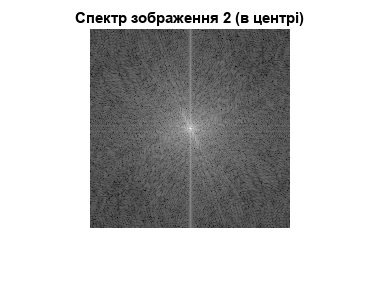

F4 = fft2(I2); 
S4=abs(F4); 
Fc4 = fftshift(S4); 
Slog4=log(1+Fc4); 
imshow(Slog4, [ ]);
title('Спектр зображення 2 (в центрі)');

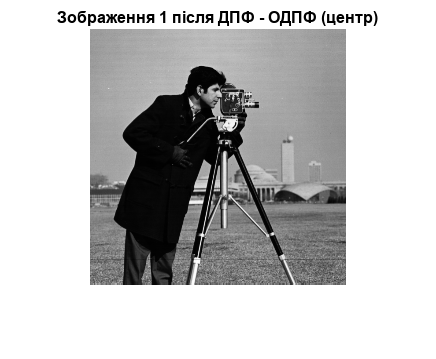

F3 = fft2(I1); 
Fc3= fftshift(F3); 
Fdc3 = ifftshift(Fc3);
If3 = ifft2(Fdc3); 
imshow(If3, []);
title('Зображення 1 після ДПФ - ОДПФ (центр)');

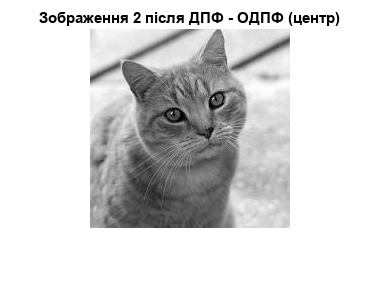

F4 = fft2(I2); 
Fc4= fftshift(F4); 
Fdc4 = ifftshift(Fc4);
If4 = ifft2(Fdc4); 
imshow(If4, []);
title('Зображення 2 після ДПФ - ОДПФ (центр)');

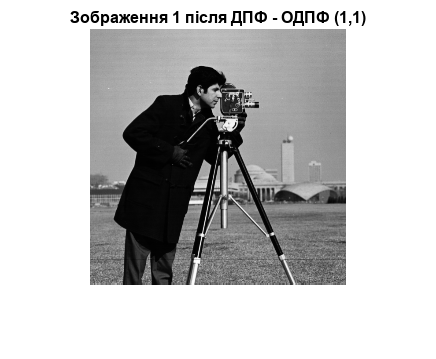

F3 = fft2(I1); 
If1 = ifft2(F3); 
imshow(If1, []);
title('Зображення 1 після ДПФ - ОДПФ (1,1)');

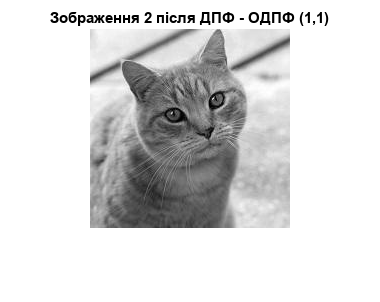

F2 = fft2(I2); 
If2 = ifft2(F2); 
imshow(If2, []);
title('Зображення 2 після ДПФ - ОДПФ (1,1)');

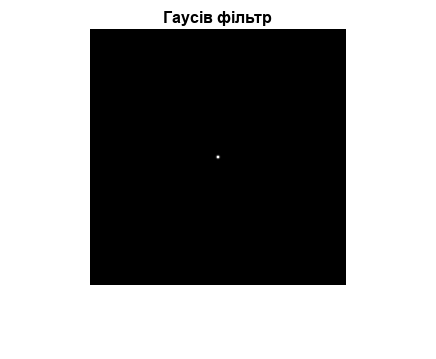

% Створення двовимірного фільтра з Gaussian фільтром

[M, N] = size(I1); 
sigma = 1;  % параметр для фільтрації
h = fspecial('gaussian', [M, N], sigma);
imshow(h, []);
title('Гаусів фільтр');

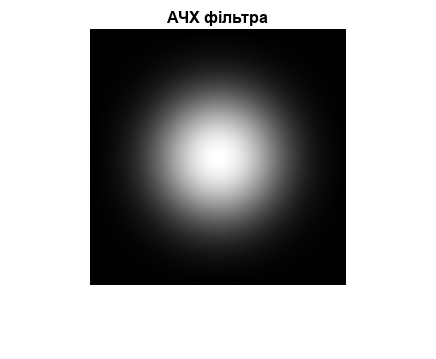

H = fft2(h);
H_shifted = fftshift(H);
imshow(log(1 + abs(H_shifted)), []); title('АЧХ фільтра'); % вигляд частотної характеристики даного фільтра

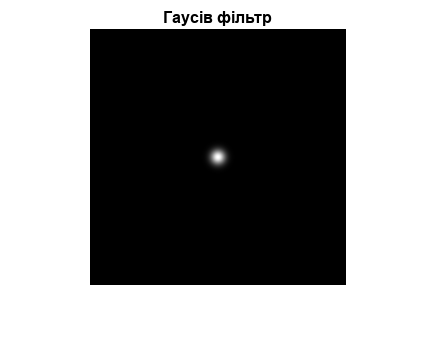

[M, N] = size(I1); 
sigma = 5;  % параметр для фільтрації
h = fspecial('gaussian', [M, N], sigma);
imshow(h, []);
title('Гаусів фільтр');

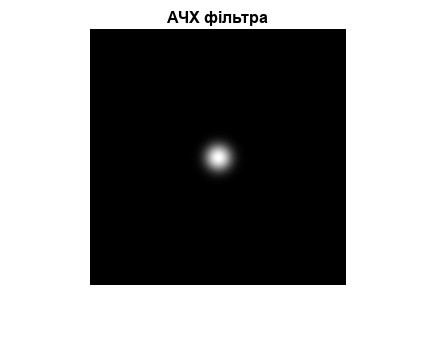

H = fft2(h);
H_shifted = fftshift(H);
imshow(log(1 + abs(H_shifted)), []); title('АЧХ фільтра'); % вигляд частотної характеристики даного фільтра

 % Зі збільшенням sigma фільтр у просторі стає ширшим, а в частотній
 % області – вужчим, збільшення значення sigma робить фільтр більш "розмитим"

% Фільтрація у файлах